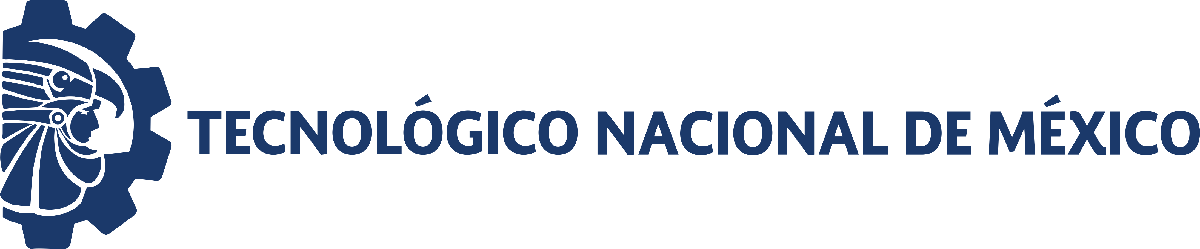                                 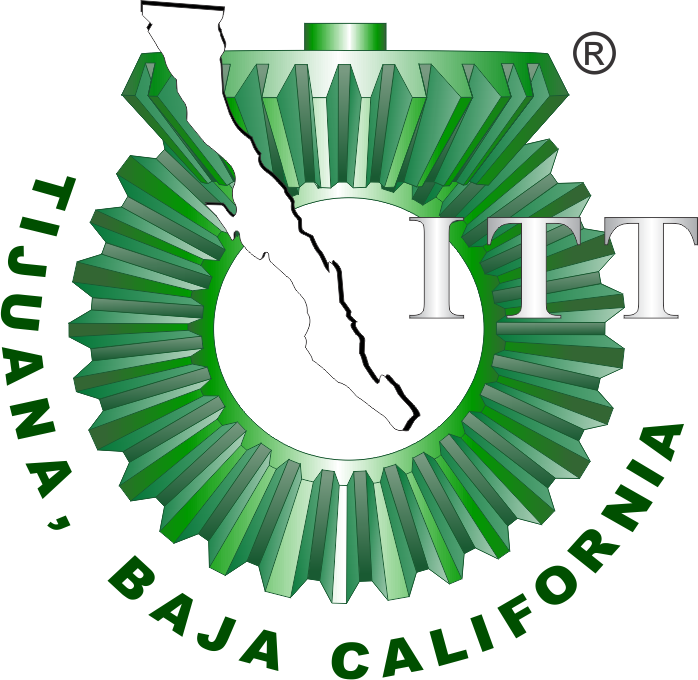

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

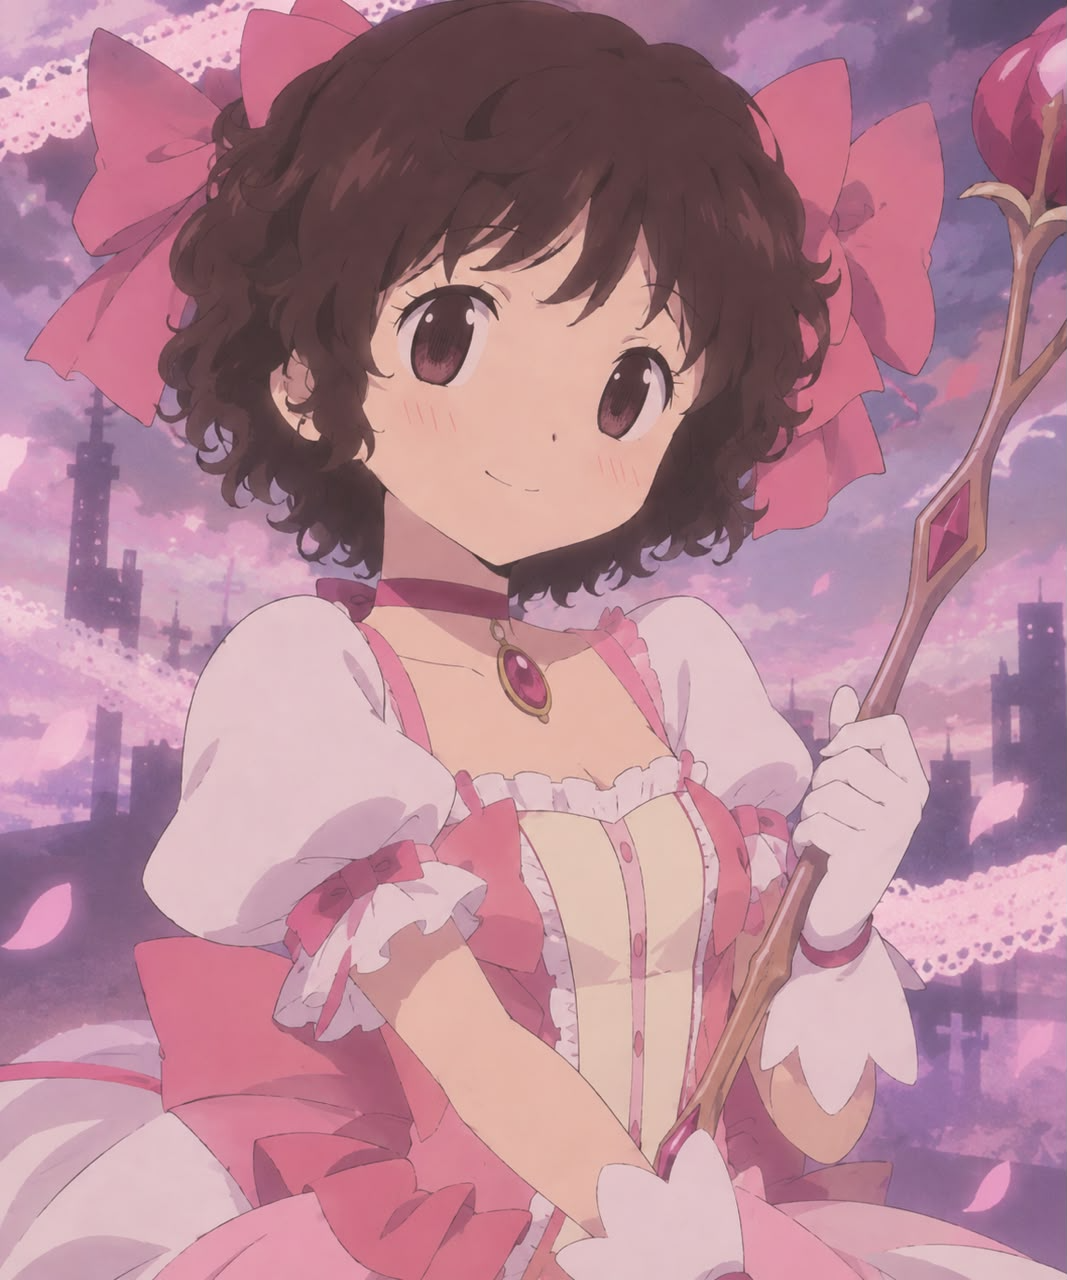

Nombre del alumno: **Nicole Arredondo Arevalo**

Número de control: 23212179

Correo institucional: L23212179**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema3')
parameters.StopTime = '10'

parameters = struct with fields:
    StopTime: '10'


parameters.Solver = 'ode15s'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'


parameters.MaxStep = '1e-3'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'
     MaxStep: '1e-3'


## Respuesta: Impulso Unitario

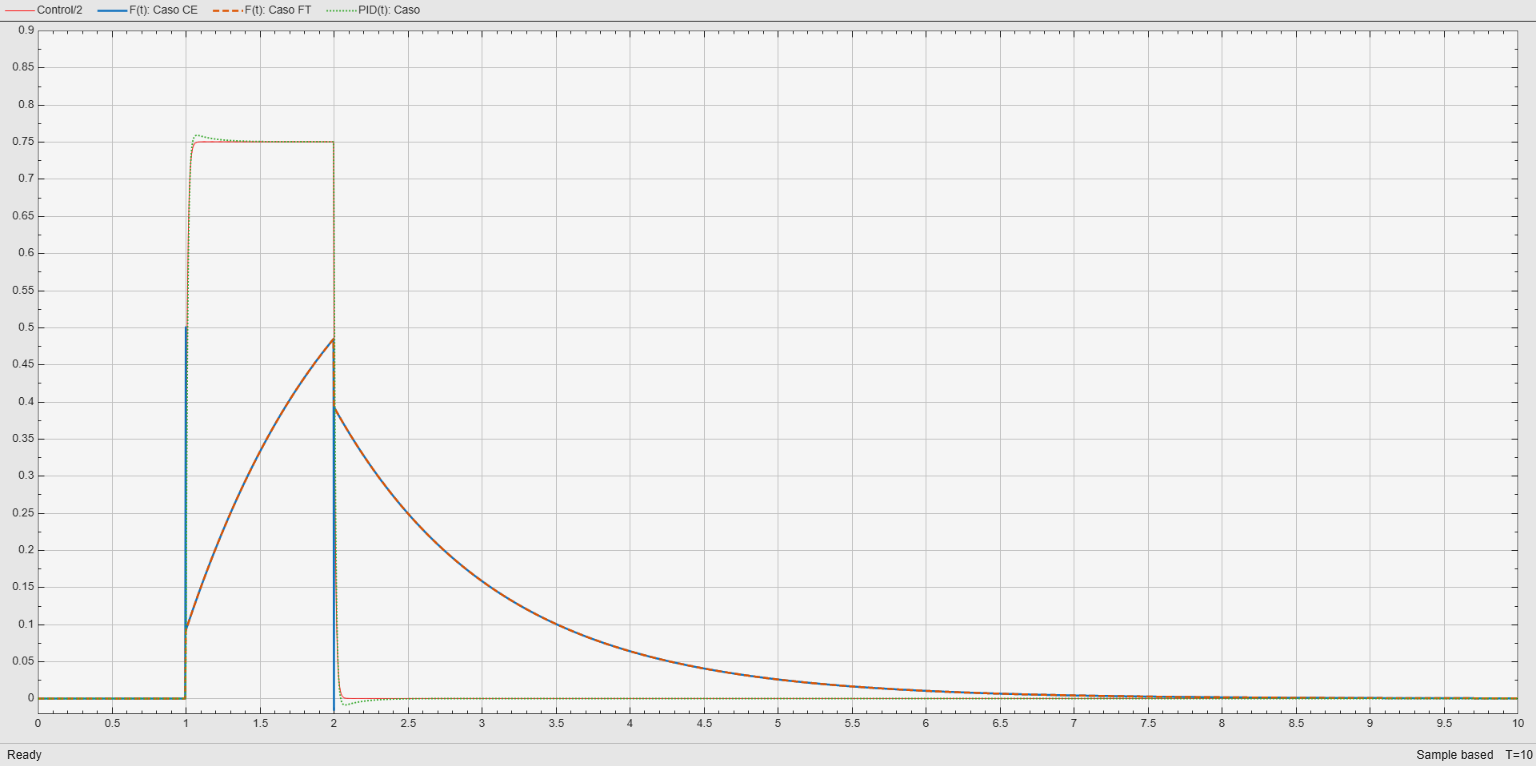

x =   Simulink.SimulationOutput:

                      F: [10124x1 double] 
                    Fsx: [10124x1 double] 
                    Fsy: [10124x1 double] 
                    PID: [10124x1 double] 
                      t: [10124x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


x=sim('sistema3',parameters)

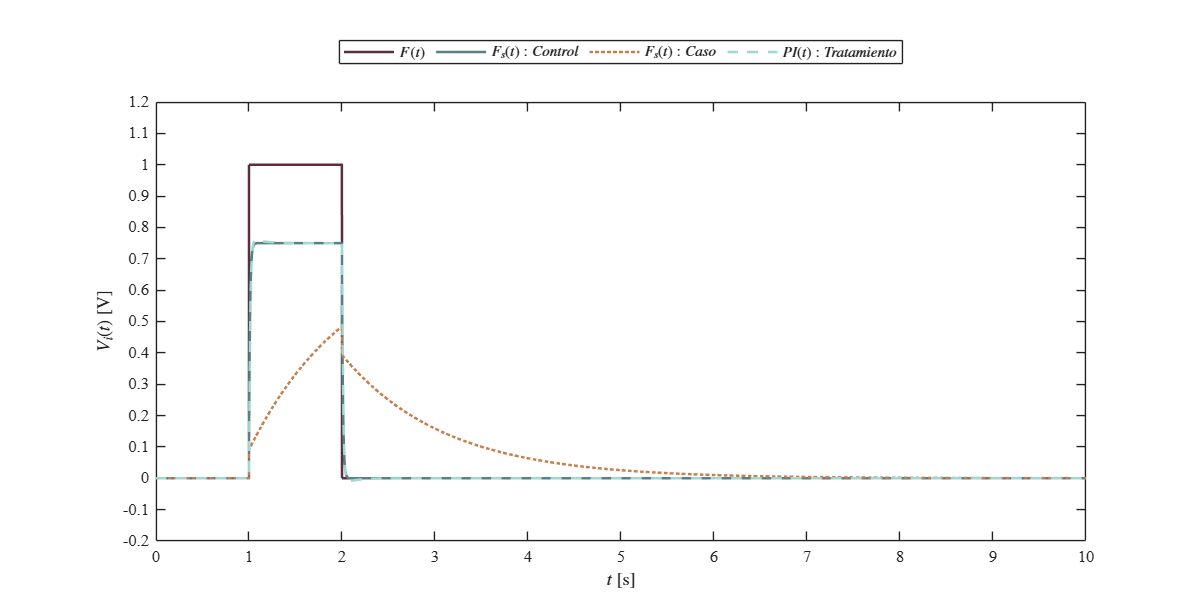

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Caso')

## **Funcion: Respuestas de la simulacion **

function plotsignals(t,F,Fsx,Fsy,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,10,5])
    set(gca, 'fontname','times new roman','fontsize',10)
    hold on; grid off; box on;
    clr1 = [92, 46, 60]/255;
    clr2 = [87, 128, 136]/255;
    clr3 = [202, 126, 76]/255;
    clr4 = [157, 217, 210]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    plot(t,F,'-',t,Fsx,'-',t,Fsy,':',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));

    L = legend('$F(t)$','$F_{s}(t): Control$','$F_s(t): Caso$','$PI(t): Tratamiento$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')

    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.2 1.2]); yticks(-0.2:0.1:1.2)

    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')

end